# Exemple 1: Constant loaded column

We assume $EA$ constant (homogeneous column).

# 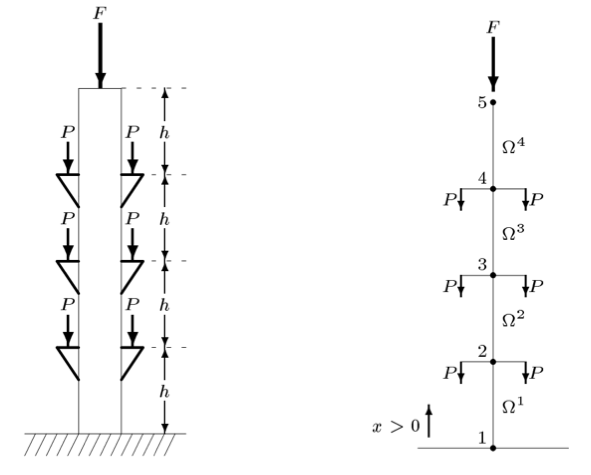

with,


$$  \begin{array}{l}
  h = 4.5\text{ m }\\
  P = 11.0\times 10^{4}\text{ N }\\
  F = 3.0\times 10^{5}\text{ N }\\
  E = 2.0\times 10^{11}\text{ N / m$^{2}$ }\\
  A = 250\text{ cm$^{2}$ }
  \end{array}
$$


The equation of the elasticity,

$ -\frac{\mathrm{d}}{\mathrm{d} x}\left(EA\frac{\mathrm{d} u}{\mathrm{d}
    x}\right) = 0
$,

is actually a particualr case of the model equation, i.e., of


$$  -\frac{\mathrm{d}}{\mathrm{d} x}\left(a_{1}(x)\frac{\mathrm{d} u}{\mathrm{d}
  x}\right) + a_{0}(x)u = f(x),
$$


with $a_{1}(x) = A E$, $a_{0}\equiv 0$, and $f\equiv 0$ (no weight is considered).

clearvars
close all

L = 18;  %m
h = 4.5; %m
P = 11.0e4; %N
Force = 3.0e5; %N
E = 2.0e11; %N/m^2
A = 0.025;  %m^2

elem = [1, 2; 
        2, 3; 
        3, 4;
        4, 5];

nodes = (0:h:L)'

nodes =          0
    4.5000
    9.0000
   13.5000
   18.0000




numElem = size(elem, 1);
numNodes = size(nodes, 1);

K = zeros(numNodes);
F = zeros(numNodes,1);
Q = zeros(numNodes,1);
u = zeros(numNodes,1);

Ke = A*E*[1, -1; -1, 1]/h;
disp(Ke)

   1.0e+09 *

    1.1111   -1.1111
   -1.1111    1.1111



Acoplem les matrius

K

K =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



for e = 1:numElem %Acoplem les matrius
    rows = [elem(e,1); elem(e,2)];
    cols = rows;
    K(rows,cols) = K(rows,cols) + Ke
end

K = 1.0e+09 *

    1.1111   -1.1111         0         0         0
   -1.1111    1.1111         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


K = 1.0e+09 *

    1.1111   -1.1111         0         0         0
   -1.1111    2.2222   -1.1111         0         0
         0   -1.1111    1.1111         0         0
         0         0         0         0         0
         0         0         0         0         0


K = 1.0e+09 *

    1.1111   -1.1111         0         0         0
   -1.1111    2.2222   -1.1111         0         0
         0   -1.1111    2.2222   -1.1111         0
         0         0   -1.1111    1.1111         0
         0         0         0         0         0


K = 1.0e+09 *

    1.1111   -1.1111         0         0         0
   -1.1111    2.2222   -1.1111         0         0
         0   -1.1111    2.2222   -1.1111         0
         0         0   -1.1111    2.2222   -1.1111
         0         0         0   -1.1111    1.1111


Imposem les condicions de contorn

% Condicions de contorn naturals
Q(2:4) = -2*P

Q =            0
     -220000
     -220000
     -220000
           0


Q(5) = -Force

Q =            0
     -220000
     -220000
     -220000
     -300000




% Condicions de contorn essencials
u(1) = 0.0;

%Reduced system
Fm = Q(2:5) + F(2:5) - K(2:5,1)*u(1)

Fm =      -220000
     -220000
     -220000
     -300000


Km = K(2:5,2:5);

%Solve the reduced system
um= Km\Fm;

u(2:5) = um;

for i = 1:numNodes
    fprintf("u(%d) = %12.5e\n",i,u(i)*1000)
end

u(1) =  0.00000e+00
u(2) = -8.64000e-01
u(3) = -1.53000e+00
u(4) = -1.99800e+00
u(5) = -2.26800e+00


Post process: find Q

Q = K*u - F

Q =       960000
     -220000
     -220000
     -220000
     -300000


for i = 1:numNodes
    fprintf("Q(%d) = %12.5e\n",i,Q(i)*1000)
end

Q(1) =  9.60000e+08
Q(2) = -2.20000e+08
Q(3) = -2.20000e+08
Q(4) = -2.20000e+08
Q(5) = -3.00000e+08
